clc
clear all
close all
addpath("functions")

## **1. GP complexity**

This section of the code is dedicated to answering question 3.1 and all its 5 sub-questions.

%Assigning given values
hyp = [0.05;1]; %defining hyper parameters
Nd = [10 15 20];%different Nd values for data generation
N = Nd.^3;

#### Testing GPregression for differently sized data sets

%For loop where the output of the GPregression function is saved per
%iteration and dataset instance. Multiple runs (the j for loop) are made so
%we can more accurately calculate the average time it takes for differently
%sized datasets to run through GPregression.
%j_lim = 10;
i_lim = length(Nd);

for i = 1:length(Nd)  %Second for loop for each dataset with a different Nd value.
    i
    %generate dataset
    [X,y,Xstar] = getdata(Nd(i),hyp);
    if Nd(i) == 10
        X1 = X;
        y1 = y;
        Xstar1 = Xstar;
    end

    %Perform GP regression, time it and calculate the models mean and covariance for
    %new points and kernel matrix for training points.
    tic
    [GPmean, GPcov, k_matrix,inverse_time, mean_time, covariance_time] = GPregression(X,y,Xstar,hyp);
    elapsed_time = toc
    
    %seperate line in order to calculate average elapsed time later on
    %in the code
    elapsed_times(i) = elapsed_time;

    %Save relevantdata in results parameter.
    %results.GPmodel = GPmodel;
    %results.predictions = predictions;
    results.mean = GPmean;
    results.cov = GPcov;
    results.k_matrix = k_matrix;
    results.elapsed_time = elapsed_time;
    results.Nd = Nd(i);

    %extra output to find the time
    results.inverse_time = inverse_time; 
    results.mean_time =  mean_time; 
    results.covariance_time =  covariance_time;

    %allocate output of the model
    GP_data{i} = results;
end

i = 1

inverse_time = 0.2126

pre_allocation_time = 0.2232

mean_time = 6.3090e-04

covariance_time = 0.3492

elapsed_time = 0.3725

i = 2

inverse_time = 5.3406

pre_allocation_time = 5.9917

mean_time = 0.0040

covariance_time = 5.0956

elapsed_time = 5.1311

i = 3

inverse_time = 56.8748

pre_allocation_time = 56.5836

mean_time = 0.0198

covariance_time = 39.6674

elapsed_time = 39.8096


% Calculate the average elapsed time per Nd value
average_elapsed_time = mean(elapsed_times, 1);

% Display the average elapsed times
for i = 1:length(Nd)
    fprintf('Average elapsed time for Nd = %d: %.4f seconds\n', Nd(i), average_elapsed_time(i));
end

Average elapsed time for Nd = 10: 0.3725 seconds
Average elapsed time for Nd = 15: 5.1311 seconds
Average elapsed time for Nd = 20: 39.8096 seconds


#### Plotting 3D results for N=1000

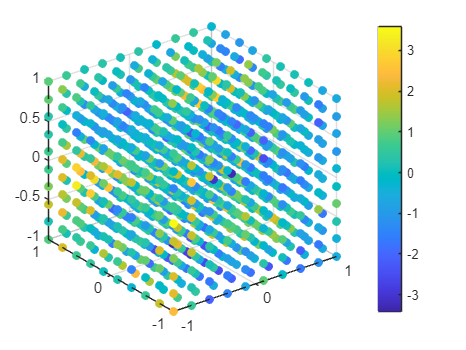

%Getting predictions of model for Nd = 10
%preds = GP_data{1}.predictions;
preds = GP_data{1}.mean;

%3D scatterplot of data + colorbar
scatter3(X1(:,1),X1(:,2),X1(:,3),[],y1,'filled')
colorbar;

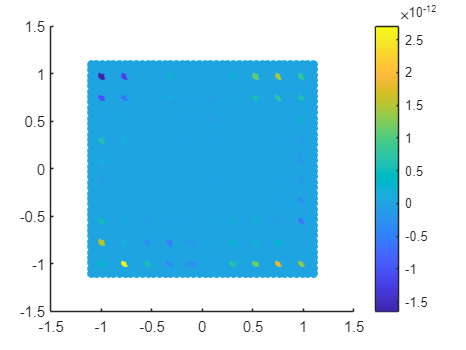


%Scatterplot of predictions
scatter(Xstar1(:,1),Xstar1(:,3),[],preds,'filled')
colorbar;

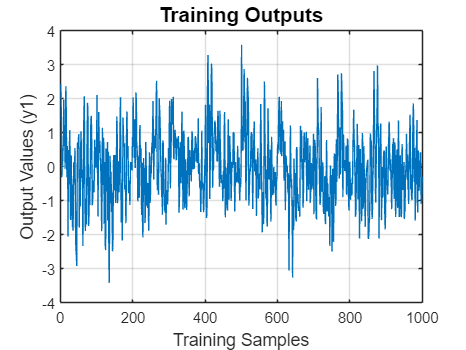


%Additional plots to understand the data and for the report
figure; %Output data plot
plot(y1); 
title('Training Outputs', 'FontSize', 14);
xlabel('Training Samples', 'FontSize', 12);
ylabel('Output Values (y1)', 'FontSize', 12);
grid on;

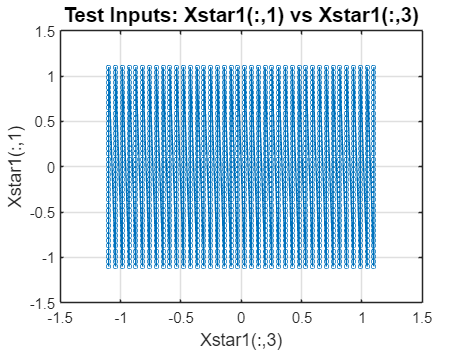


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,3), Xstar1(:,1),'o-', 'MarkerSize', 3);
title('Test Inputs: Xstar1(:,1) vs Xstar1(:,3)', 'FontSize', 14);
xlabel('Xstar1(:,3)', 'FontSize', 12);
ylabel('Xstar1(:,1)', 'FontSize', 12); 
grid on;  

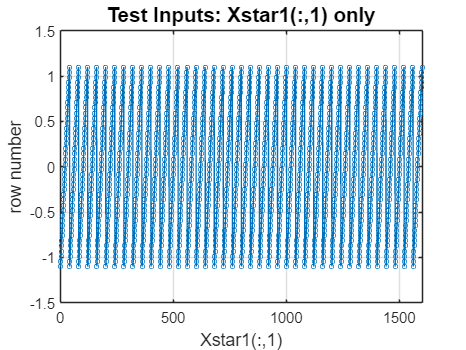


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,1), 'o-',  'MarkerSize', 3);
title('Test Inputs: Xstar1(:,1) only', 'FontSize', 14);
xlabel('Xstar1(:,1)', 'FontSize', 12);
ylabel('row number', 'FontSize', 12); 
grid on;  

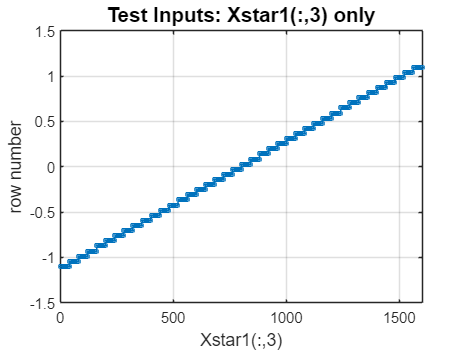


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,3), 'o-', 'MarkerSize', 3);
title('Test Inputs: Xstar1(:,3) only', 'FontSize', 14);
xlabel('Xstar1(:,3)', 'FontSize', 12);
ylabel('row number', 'FontSize', 12); 
grid on;

## 2. Kernel Matrix as Tensor Train

K = GP_data{1}.k_matrix;        %Kernel matrix for 10^3 inputs.
I = [10 10 10]; J = [10 10 10]; %Given size dimensions
eps = 1e-10;                    %Given epsilon value

%reshaping matrix into tensor in order to make it ready for TT_SVD
K_tensor = reshape(K,[I, J]);
K_tensor1 = permute(K_tensor,[1,4,2,5,3,6]);
K_tensor2 = reshape(K_tensor1,I(1)*J(1),I(2)*J(2),I(3)*J(3));

%Turning the tensor into a tensor train.
[tt_K1,rel_err1] = TT_SVD(K_tensor1,eps);
[tt_K2,rel_err2] = TT_SVD(K_tensor2,eps);

%calculating the compression ratio
num_el_tt1 = 0;
num_el_tt2 = 0;

for i = 1:length(tt_K1)-1
    num_el_tt1 = num_el_tt1 + numel(tt_K1{i});
end
for j = 1:length(tt_K2)-1
    num_el_tt2 = num_el_tt2 + numel(tt_K2{j});
end

fprintf("the number of elements of the first tensor train is %d and of the 2nd tensor train %d",num_el_tt1,num_el_tt2);

the number of elements of the first tensor train is 600 and of the 2nd tensor train 300


comp_ratio1 = num_el_tt1/numel(K)

comp_ratio1 = 6.0000e-04

comp_ratio2 = num_el_tt2/numel(K)

comp_ratio2 = 3.0000e-04